# Lecture 7: Fourier Transform

# Part 1: Periodic Signals Example

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture7 - Fourier Transform

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
close all, clearvars, clc;

## Cosine functions with different frequencies

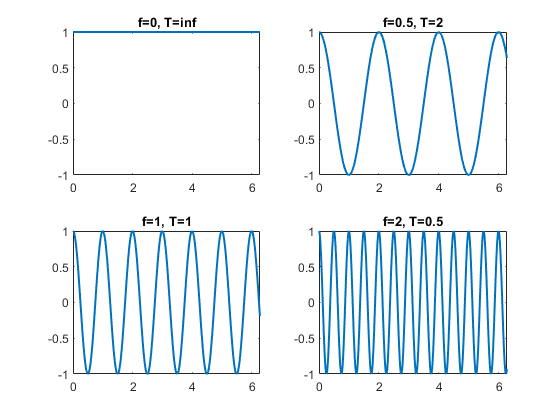

t = [0:0.01:2*pi];

% display cosine functions in the form of cos(2*pi*f*t)
figure, subplot(2,2,1), plot(t, cos(2*pi*0*t), 'LineWidth', 1.5), axis([0 2*pi, -1 1]), title('f=0, T=inf')
subplot(2,2,2), plot(t, cos(2*pi*0.5*t), 'LineWidth', 1.5), axis([0 2*pi, -1 1]), title('f=0.5, T=2')
subplot(2,2,3), plot(t, cos(2*pi*1*t), 'LineWidth', 1.5), axis([0 2*pi, -1 1]), title('f=1, T=1')
subplot(2,2,4), plot(t, cos(2*pi*2*t), 'LineWidth', 1.5), axis([0 2*pi, -1 1]), title('f=2, T=0.5')

## Sum of periodic signals (1)

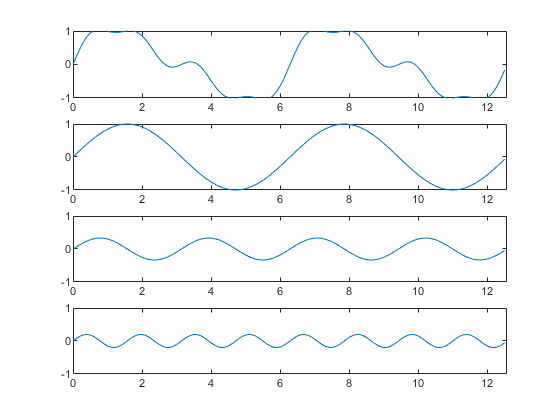

x = [0:0.1:4*pi];

f1 = sin(x);
f2 = sin(2*x)/3;
f3 = sin(4*x)/5;
f = f1+f2+f3;

figure,subplot(4,1,1), plot(x,f), axis([0 4*pi -1 1])
subplot(4,1,2), plot(x,f1), axis([0 4*pi -1 1])
subplot(4,1,3), plot(x,f2), axis([0 4*pi -1 1])
subplot(4,1,4), plot(x,f3), axis([0 4*pi -1 1])

## Sum of periodic signals (2)

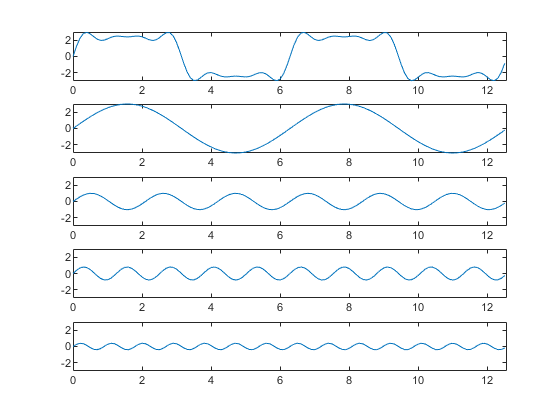

x = [0:0.1:4*pi];

f1 = 3*sin(x);
f2 = sin(3*x);
f3 = 0.8*sin(5*x);
f4 = 0.4*sin(7*x);
f = f1+f2+f3+f4;

figure,subplot(5,1,1), plot(x,f), axis([0 4*pi -3 3])
subplot(5,1,2), plot(x,f1), axis([0 4*pi -3 3])
subplot(5,1,3), plot(x,f2), axis([0 4*pi -3 3])
subplot(5,1,4), plot(x,f3), axis([0 4*pi -3 3])
subplot(5,1,5), plot(x,f4), axis([0 4*pi -3 3])